# Part 2: Modeling

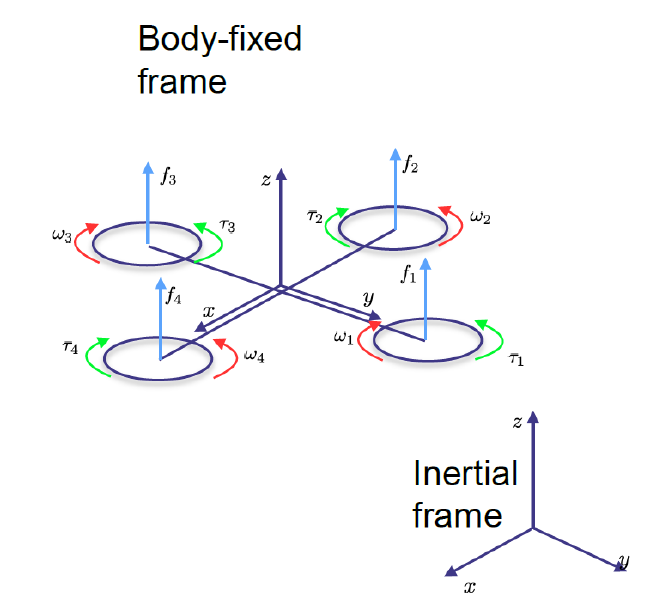

clear all
m = 0.5;    %[kg]           the drone mass in the center of gravity of the drone
L = 0.225;  %[m]            length of each arm of the quadrotor frame, the distance of the motors from the CoG
k = 0.01;   %[N*s^2/rad^2]  the overall aerodynamic coefficient necessary to compute the lift of the propellers
b = 0.01;   %[Nm*s^2/rad^2] the overall aerodynamic coefficient necessary to compute the drag torque of the propellers
D = diag([0.01, 0.01, 0.01]); 
            %[N*s/m]        matrix representing the the drag on the UAV moving in air with velocity p_dot
Ixx = 3e-6; %[Nms^2/rad]    the moment of inertia on the principal axis x
Iyy = 3e-6; %[Nms^2/rad]    the moment of inertia on the principal axis y
Izz = 1e-5; %[Nms^2/rad]    the moment of inertia on the principal axis z
MoI = diag([Ixx, Iyy, Izz]);
g = [0, 0, -9.81]';
            % [m/s^2]       gravity acts along the z-axis of the inertial frame of reference



$\textbf{p}[m]$ is the position of the CoG of the UAV w.r.t a fixed inertial frame of reference.


$$\textbf{p}=[x,y,z]^T$$


$\Theta[rad]$ is the representation of the rotation of the body-fixed frame w.r.t the fixed inertial frame of reference, accroding to the Roll-Pitch-Yaw angular representation.

  
$$\Theta=[\phi, \theta, \psi]^T$$


## 2.1.1 Define the rotation matrix representing the orientation of the body-fixed frame w.r.t. the inertial frame. 

Rotation from inertial frame to body-fixed frame


$$R_{ZYX}(\phi, \theta, \psi)=R_z(\phi)R_y(\theta)R_x(\psi)$$


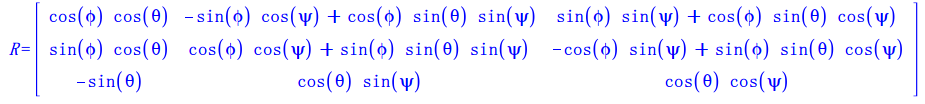

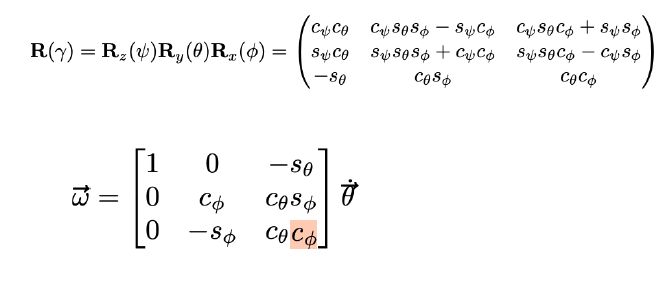

## 2.1.2 Define the relation between the angular velocity Θ and the rotational velocity of the body-fixed frame ω.

From body-fixed to inerital frame


$$\dot{\theta}=[B(\theta)]\omega $$


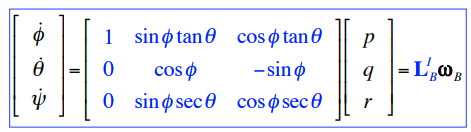

From inerital frame to body-fixed frame


$$\omega=[B(\theta)]^{-1}\dot{\theta}$$


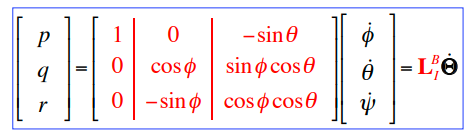

## 2.1.3 Write the linear and angular dynamic equation of the drone in compact form, and clearly show each component of the equation explicitly

Force

Propeller total trust

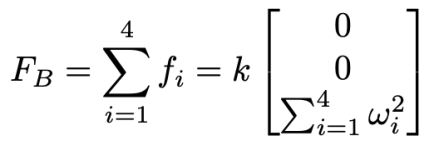

Viscous damping

model friction as a force proportional to the linear velocity in each direction.

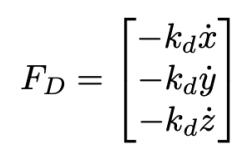

Total torque around z-axis of the body

Total torque on x-asis

Total torque on y-axis

Total body torque

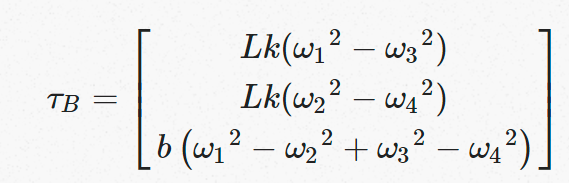

Linear motion equations (in the inertial frame):

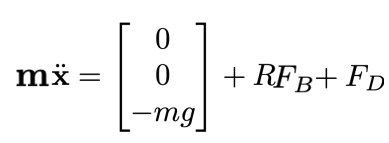  

Angular motion equations(in body-fixed frame):

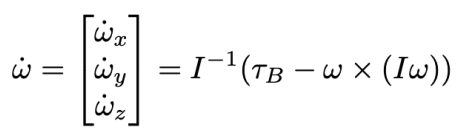  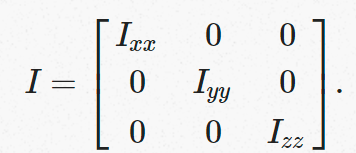

after simplification:

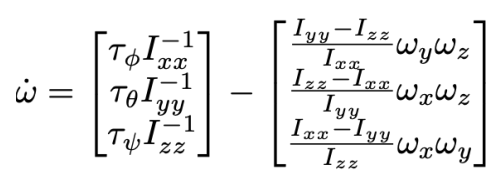


$$x_1 = [x,y,z]^T - position \\
x_2 = [\dot{x}, \dot{y}, \dot{z}]^T - linear \ velocity \\
x_3 = [\phi, \theta, \psi]^T - Roll-Pitch-Yaw \ angles \\
x_4 = [\omega_x, \omega_y, \omega_z]^T - angular \ velocity$$


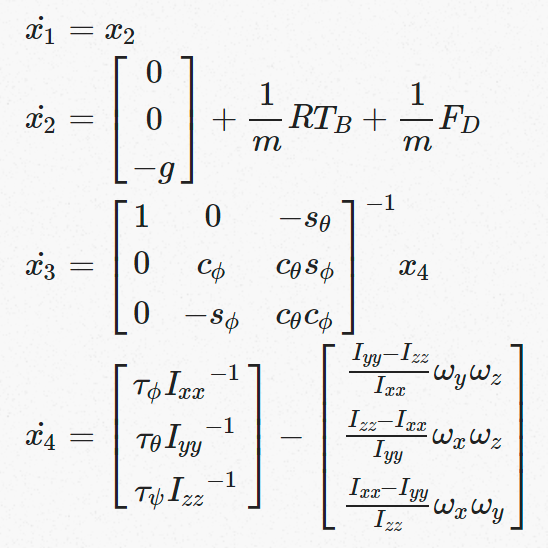

## 2.1.4 Make a MATLAB/Simulink model of the drone, given initial conditions 

% simTime
simTime = 10.0;

% [m] position of the CoG of the UAV w.r.t. a fixed inertial frame of reference
p = [0, 0, 0]';     %[x, y, z]

% [m/s] linear velocity of the CoG of the UAV w.r.t. a fixed inertial frame of reference
p_dot = [0, 0, 0]'; 

% [rad] the representation of the rotation of the body-fixed w.r.t. inertial frame
Theta = [0, 0, 0]';     %   [phi, theta, psi] = [roll, pitch, yaw]

% [rad/s] the angular velocity of the body-fixed frame w.r.t the inertial frame (expressed in body fixed frame)
omega = [0, 0, 0]';

% [rad/s] vector of the angular speed of the four propellers
RPM = [0, 0, 0, 0]';

### 1) Make a plot of p and Θ, given Ω = [0, 0, 0, 0]T and explain the result

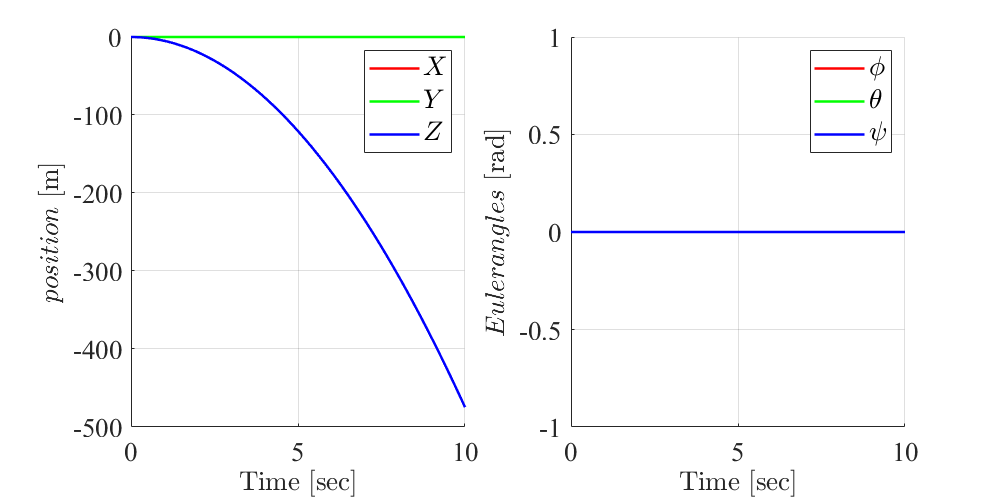

TakeStep = 1; % 1 for step input
RPM = [0, 0, 0, 0]';
simOut = sim("My_Nonlinear_new.slx");
plotSimOutput(simOut.yout{1}.Values.Time, simOut.yout{1}.Values.Data)

### 2) Make a plot of p and Θ, given Ω = [10000, 0, 10000, 0]T and explain the result

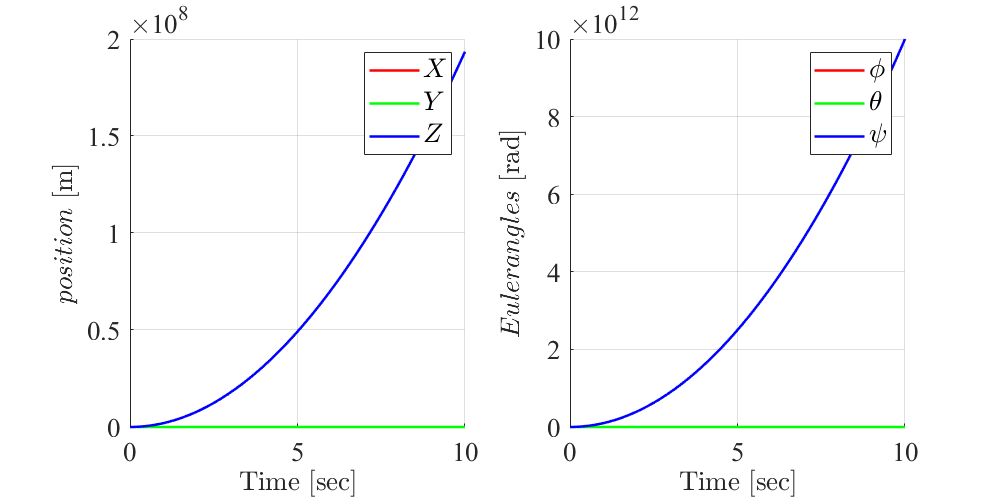

RPM = [10000, 0, 10000, 0]';
simOut = sim("My_Nonlinear_new.slx");
plotSimOutput(simOut.yout{1}.Values.Time, simOut.yout{1}.Values.Data)

### 3) Make a plot of p and Θ, given Ω = [0, 10000, 0, 10000]T and explain the result

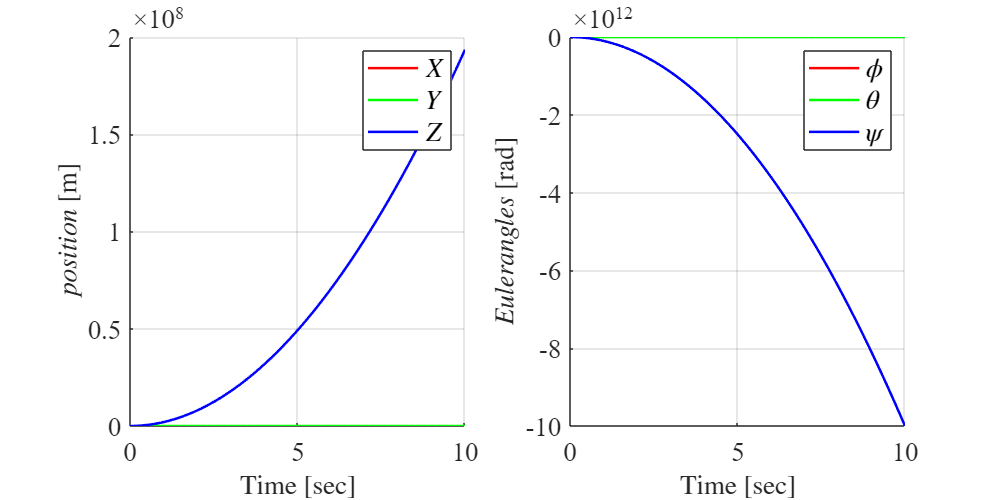

RPM = [0, 10000, 0, 10000]';
simOut = sim("My_Nonlinear_new.slx");
plotSimOutput(simOut.yout{1}.Values.Time, simOut.yout{1}.Values.Data)

## Exercise 2.2 UAV model using quaternions to represent the rotations

From quaternion to rotation matrix

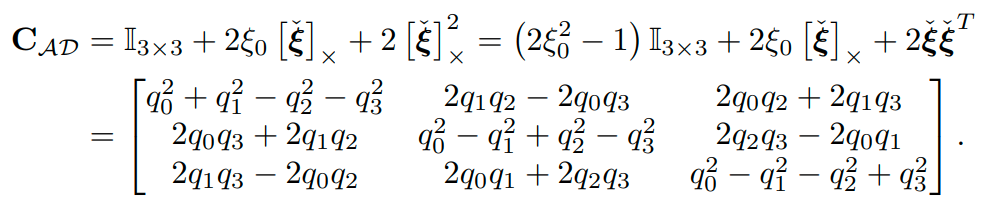

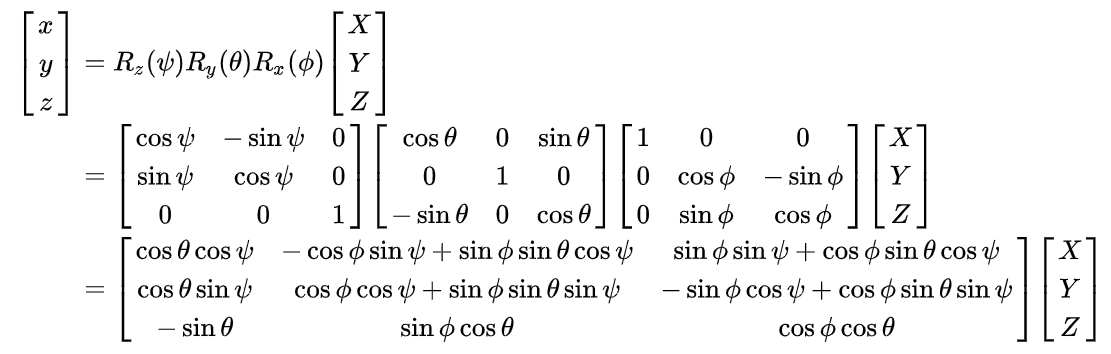

From rotation matrix to Euler angles

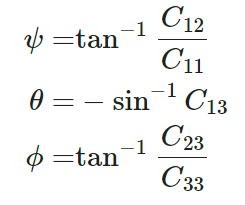

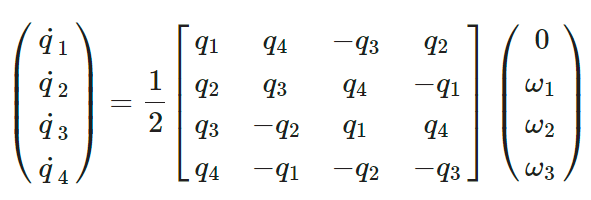

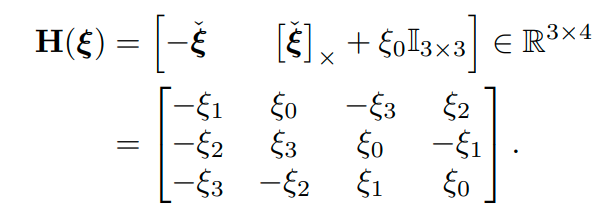


$$x_1 = [x,y,z]^T - position \\
x_2 = [\dot{x}, \dot{y}, \dot{z}]^T - linear \ velocity \\
x_3 = [q_0, q_1,q_2,q_3]^T - quaternion \\
x_4 = [\omega_x, \omega_y, \omega_z]^T - angular \ velocity$$


% quaternion initial condition
quat = [1,0,0,0]';

### 1) Make a plot of p and Θ, given Ω = [0, 0, 0, 0]T and explain the result

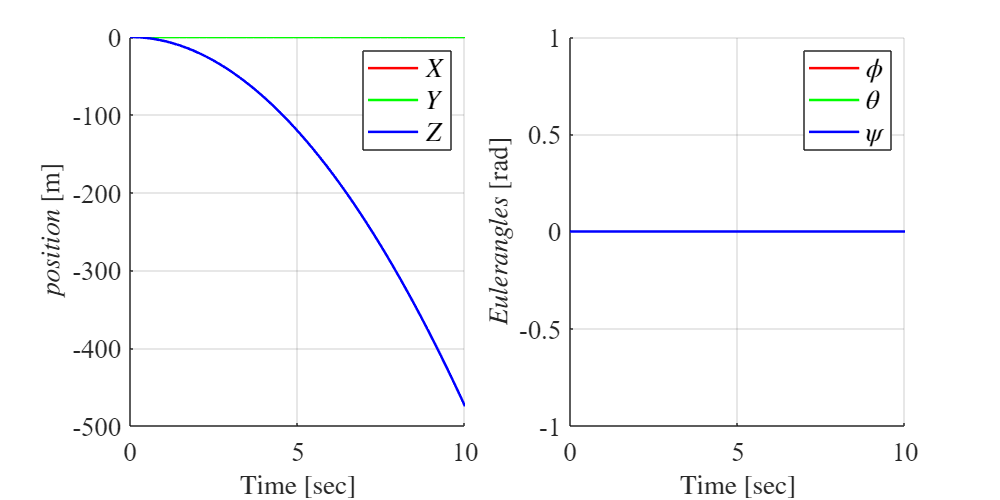

TakeStep = 1; %setting TakeStep 1 take the stepinput, setting TakeStep to 0 take the IN
RPM = [0, 0, 0, 0]';
simOut = sim('My_Nonlinear_Quaternions.slx');
plotSimOutput(simOut.yout{1}.Values.Time, simOut.yout{1}.Values.Data)

### 2) Make a plot of p and Θ, given Ω = [10000, 0, 10000, 0]T and explain the result

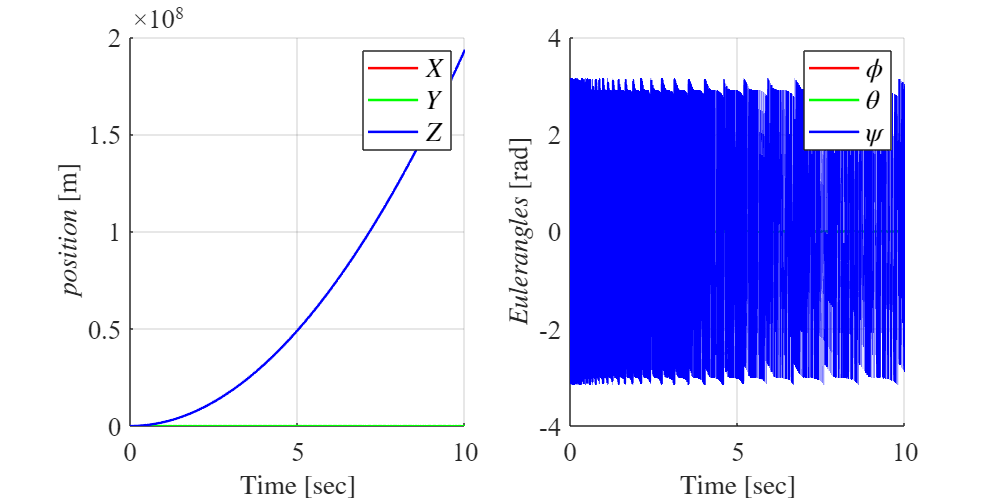

TakeStep = 1; %setting TakeStep 1 take the stepinput, setting TakeStep to 0 take the IN
RPM = [10000, 0, 10000, 0]';
simOut = sim('My_Nonlinear_Quaternions.slx');
plotSimOutput(simOut.yout{1}.Values.Time, simOut.yout{1}.Values.Data)

### 3) Make a plot of p and Θ, given Ω = [0, 10000, 0, 10000]T and explain the result

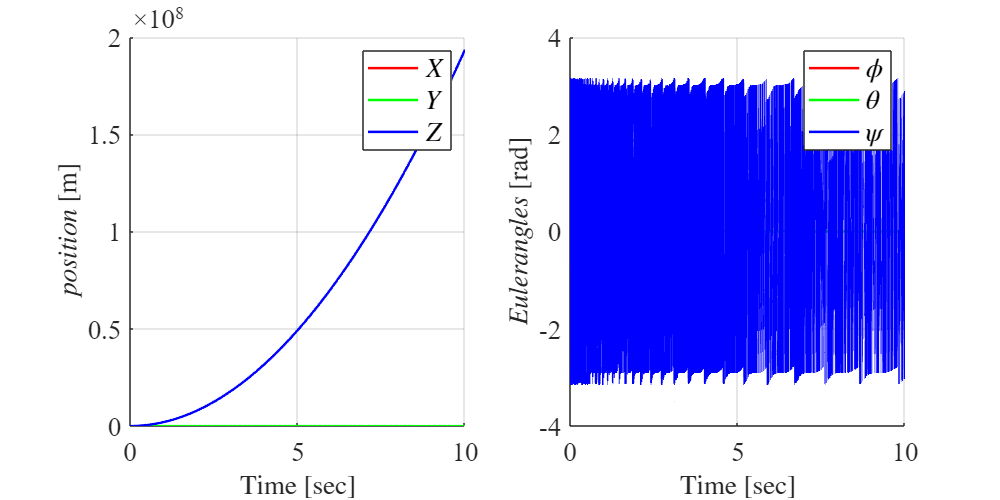

TakeStep = 1; %setting TakeStep 1 take the stepinput, setting TakeStep to 0 take the IN
RPM = [0, 10000, 0, 10000]';
simOut = sim('My_Nonlinear_Quaternions.slx');
plotSimOutput(simOut.yout{1}.Values.Time, simOut.yout{1}.Values.Data)

## Exercise 2.3 Linearize the dynamic model of the UAV in hovering conditions

x = Simulink.BlockDiagram.getInitialState('My_Nonlinear_new')

x = Simulink.SimulationData.Dataset 'xFinal' with 4 elements

                        Name  BlockPath                                
                        ____  ________________________________________ 
    1  [1x1 State]      ''    ...r_new/Angular Acceleration Integrator
    2  [1x1 State]      ''    ...linear_new/Euler Angle Rate Itegrator
    3  [1x1 State]      ''    ...ar_new/Linera Acceleration Integrator
    4  [1x1 State]      ''    ...linear_new/Linera Velocity Integrator

  - Use braces { } to access, modify, or add elements using index.


### Find hovering conditions numerically, using Matlab function *trim()*

TakeStep = 0;
p = [0,0,0]';
Theta = [0, 0, 0]';
x0 = [p;p_dot;Theta;omega]

x0 =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


x0 = zeros(12,1);
u0 = ones(4,1);
y0 = [];

ix = [1 2 3 7 8 9];
iu = [];
iy = [];
[xss, uss, yss] = trim('Exercise_2_2_1_Nonlinear_new', x0, u0, y0, ix, iu, iy); % Exercise_2_2_1_Nonlinear_new My_Nonlinear_new
xss

xss = 	1.0e+-14 *

    0.0000
   -0.0000
   -0.0000
   -0.0000
    0.0000
    0.1197
         0
         0
         0
   -0.0000


yss

yss = 	1.0e+-14 *

    0.0000
   -0.0000
   -0.0000
   -0.0000
    0.0000
    0.1197


uss

uss =    11.0736
   11.0736
   11.0736
   11.0736


### Test the nonlinear model around operation point $\textbf{P}=[0,0,0]^T, \ 
\Theta=[0,0,0]^T \ 
u=uss$

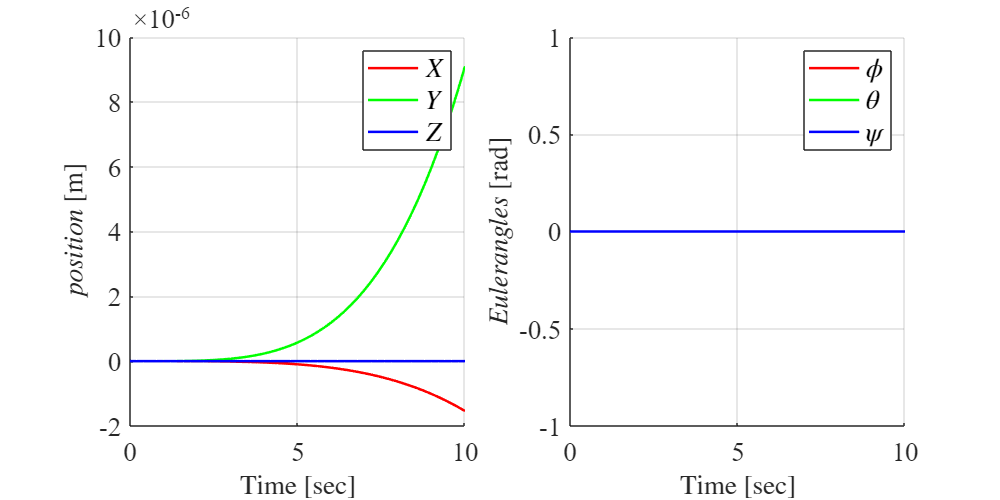

TakeStep = 1;
p = [0,0,0]';
Theta = [0, 0, 0]';
RPM = uss;
simOut = sim('My_Nonlinear_new.slx'); %My_Nonlinear_new
plotSimOutput(simOut.yout{1}.Values.Time, simOut.yout{1}.Values.Data)
subplot(1,2,2)
xlim('auto')
ylim([-1,1])

### Linearlize the nonlinear model around operation point

TakeStep = 0;
[Aa, Bb, Cc, Dd] = linmod('My_Nonlinear_new', x0, uss)

Aa =          0         0         0    1.0000         0         0         0         0         0         0         0         0
         0         0         0         0    1.0000         0         0         0         0         0         0         0
         0         0         0         0         0    1.0000         0         0         0         0         0         0
         0         0         0   -0.0100         0         0         0    9.8100         0         0         0         0
         0         0         0         0   -0.0100         0   -9.8100         0         0         0         0         0
         0         0         0         0         0   -0.0100         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0    1.0000         0         0
         0         0         0         0         0         0         0         0         0         0    1.0000         0
         0         0       

Bb = 	1.0e+04 *

         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
    0.0000    0.0000    0.0000    0.0000
         0         0         0         0
         0         0         0         0
         0         0         0         0
    1.6610         0   -1.6610         0


Cc =      1     0     0     0     0     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0     0     0     0     0
     0     0     1     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     1     0     0     0     0     0
     0     0     0     0     0     0     0     1     0     0     0     0
     0     0     0     0     0     0     0     0     1     0     0     0


Dd =      0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0


sys = ss(Aa, Bb, Cc, Dd)

sys =
 
  A = 
           x1     x2     x3     x4     x5     x6     x7     x8     x9    x10    x11    x12
   x1       0      0      0      1      0      0      0      0      0      0      0      0
   x2       0      0      0      0      1      0      0      0      0      0      0      0
   x3       0      0      0      0      0      1      0      0      0      0      0      0
   x4       0      0      0  -0.01      0      0      0   9.81      0      0      0      0
   x5       0      0      0      0  -0.01      0  -9.81      0      0      0      0      0
   x6       0      0      0      0      0  -0.01      0      0      0      0      0      0
   x7       0      0      0      0      0      0      0      0      0      1      0      0
   x8       0      0      0      0      0      0      0      0      0      0      1      0
   x9       0      0      0      0      0      0      0      0      0      0      0      1
   x10      0      0      0      0      0      0      0      0      0      

### Test the linear model around operation point $\textbf{P}=[0,0,0]^T, \ 
\Theta=[0,0,0]^T, \ u = uss$

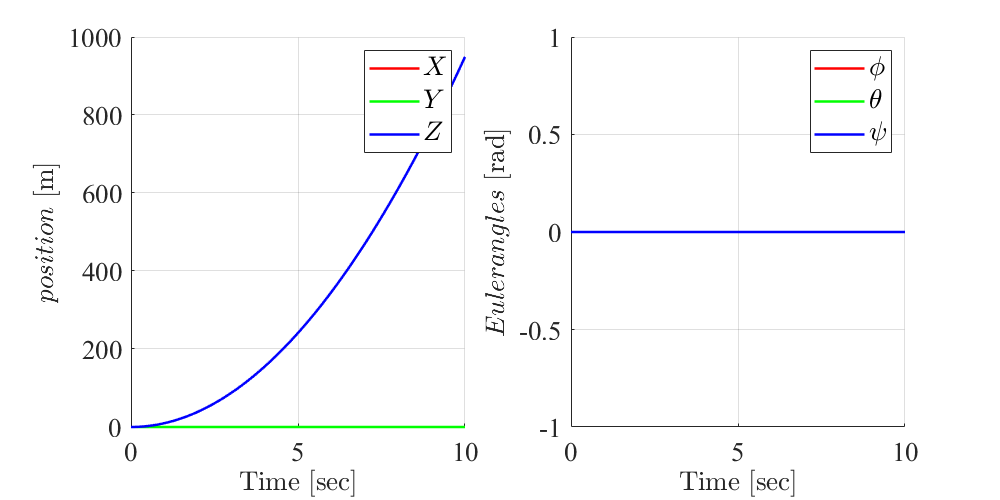

p = [0,0,0]';
Theta = [0, 0, 0]';
x0 = [p;p_dot;Theta;omega];

t = 0:0.1:10;
RPM = uss;
u = ones(length(t), 1) * RPM';
y = lsim(sys, u, t, x0);
plotSimOutput(t, y')
xlim('auto')
ylim([-1,1])

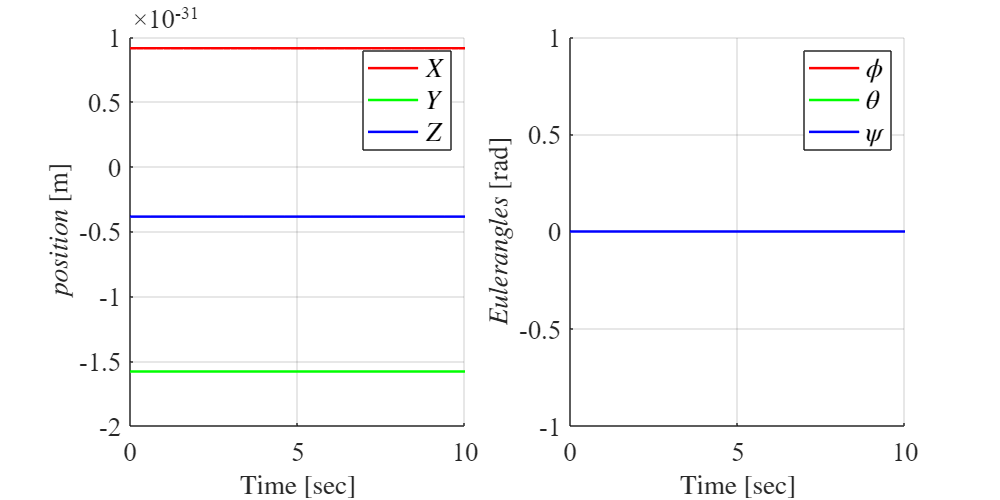

TakeStep = 1;
p = [0,0,0]';
Theta = [0, 0, 0]';
x0 = [p;p_dot;Theta;omega];
RPM = uss;
simOut = sim('My_Linear_new.slx'); %My_Linear_new Exercise_2_2_1_Linear %% difference is using x0 or xss in initial condition
plotSimOutput(simOut.yout{1}.Values.Time, simOut.yout{1}.Values.Data)
subplot(1,2,2)
xlim('auto')
ylim([-1,1])

### 1) Make a plot of p and Θ, given Ω = [0, 0, 0, 0]T and explain the result

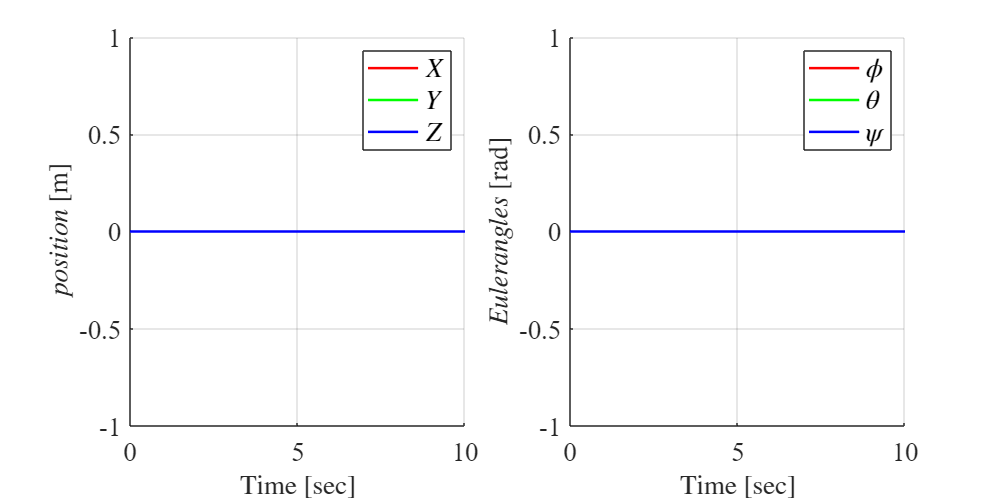

p = [0,0,0]';
Theta = [0, 0, 0]';
x0 = [p;p_dot;Theta;omega];

t = 0:0.1:10;
RPM = [0,0,0,0]';
u = ones(length(t), 1) * RPM';
y = lsim(sys, u, t, x0);
plotSimOutput(t, y')
xlim('auto')
ylim([-1,1])

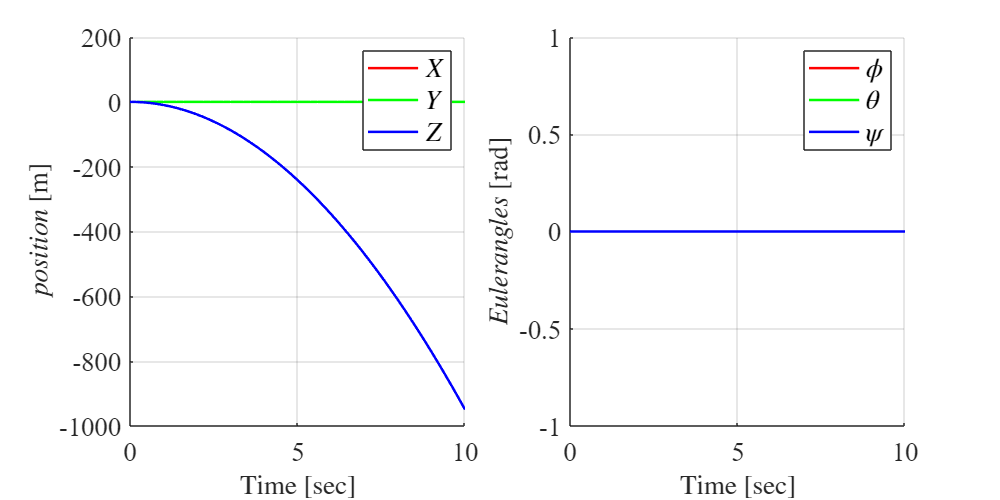

TakeStep = 1;
p = [0,0,0]';
Theta = [0, 0, 0]';
x0 = [p;p_dot;Theta;omega];
RPM = [0,0,0,0]';
simOut = sim('My_Linear_new.slx'); %My_Linear_new Exercise_2_2_1_Linear %% difference is using x0 or xss in initial condition
plotSimOutput(simOut.yout{1}.Values.Time, simOut.yout{1}.Values.Data)
subplot(1,2,2)
xlim('auto')
ylim([-1,1])

### 2) Make a plot of p and Θ, given Ω = [10000, 0, 10000, 0]T and explain the result

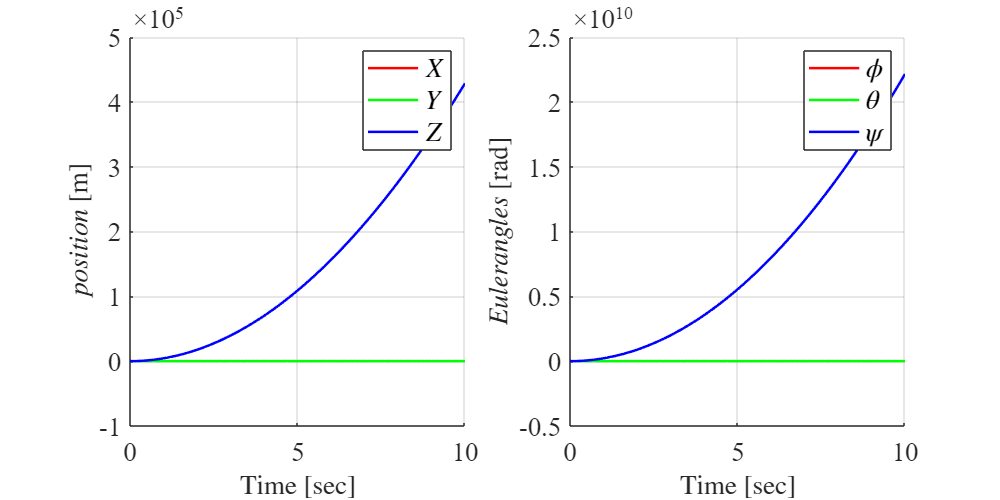

RPM = [10000,0,10000,0]';
u = ones(length(t), 1) * RPM';
y = lsim(sys, u, t, x0);
plotSimOutput(t, y')

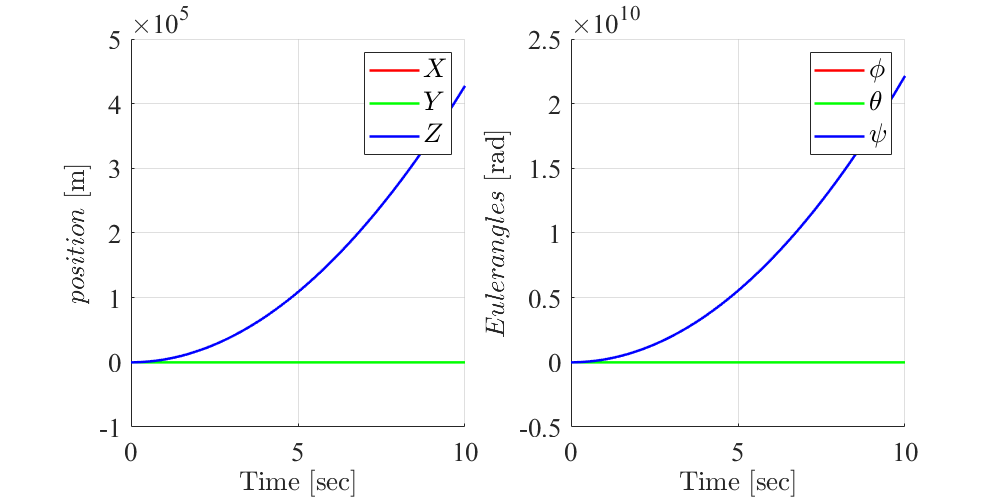

TakeStep = 1;
RPM = [10000,0,10000,0]';
simOut = sim('My_Linear_new.slx'); %My_Linear
plotSimOutput(simOut.yout{1}.Values.Time, simOut.yout{1}.Values.Data)

### 3) Make a plot of p and Θ, given Ω = [0, 10000, 0, 10000]T and explain the result

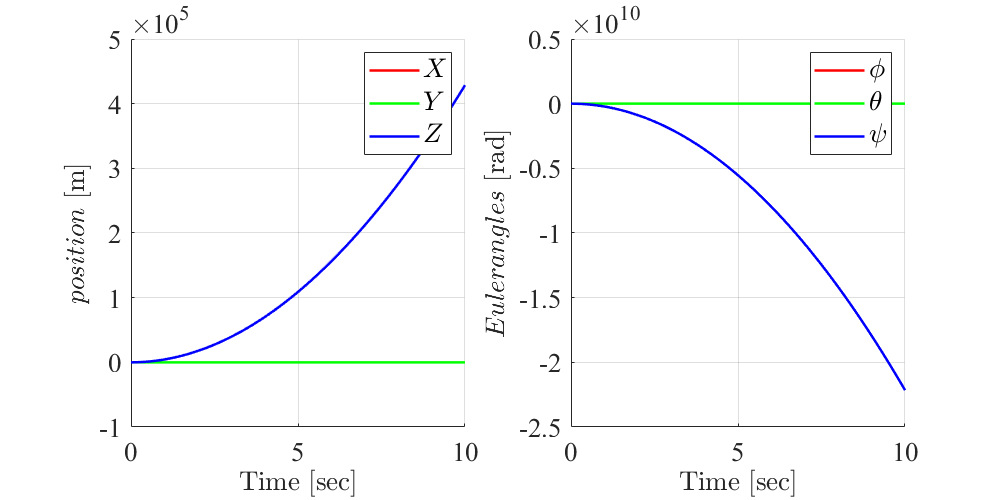

RPM = [0, 10000, 0, 10000]';
u = ones(length(t), 1) * RPM';
y = lsim(sys, u, t, x0);
plotSimOutput(t, y')

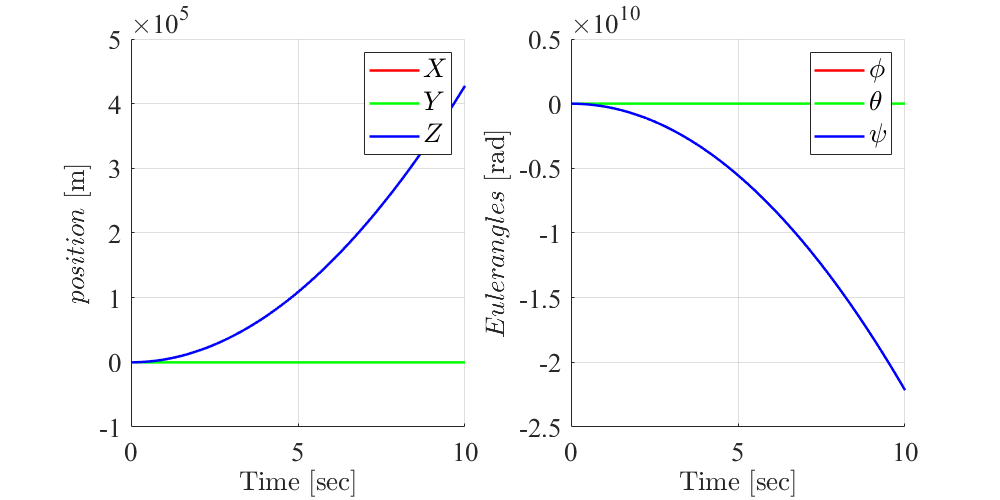

TakeStep = 1;
RPM = [0, 10000, 0, 10000]';
simOut = sim('My_Linear_new.slx'); %My_Linear
plotSimOutput(simOut.yout{1}.Values.Time, simOut.yout{1}.Values.Data)

Save variabels

save('Linear_System_parameters.mat','Aa', 'Bb', 'Cc', 'Dd', 'xss', 'uss', 'yss')

function plotSimOutput(time, data)
        
    posX = data(1,:);
    posY = data(2,:);
    posZ = data(3,:);
    
    angPhi      = data(4,:);
    angTheta    = data(5,:);
    angPsi      = data(6,:);
    
    
    figure, h1 = subplot(1,2,1); set(h1,'FontName','times','FontSize',16)
    hold on, grid on
    plot(time, posX,'r', time, posY,'g', time, posZ,'b','LineWidth',1.5)
    xlabel('Time [sec]','FontName','times','FontSize',16,'Interpreter','latex')
    ylabel('$position$ [m]','FontName','times','FontSize',16,'Interpreter','latex')
    legend('$X$', '$Y$', '$Z$', 'FontName','times','FontSize',16,'Interpreter','latex')
    h2 = subplot(1,2,2); set(h2,'FontName','times','FontSize',16)
    hold on, grid on
    plot(time, angPhi,'r', time, angTheta,'g', time, angPsi,'b', 'LineWidth',1.5)
    xlabel('Time [sec]','FontName','times','FontSize',16,'Interpreter','latex')
    ylabel('$Euler angles$ [rad]','FontName','times','FontSize',16,'Interpreter','latex')
    legend('$\phi$', '$\theta$', '$\psi$', 'FontName','times','FontSize',16,'Interpreter','latex')
    set(gcf,'units','points','position',[0,0,600,300])
end